clear; clc;
cvx_clear;

addpath './../classes'

% Define BB84 states
s0  = [1;0]

s0 =      1
     0


s1  = [0;1]

s1 =      0
     1


sp  = [1;1]/sqrt(2)

sp =     0.7071
    0.7071


sm  = [1;-1]/sqrt(2)

sm =     0.7071
   -0.7071



states = [s0, s1, sp, sm  ]

states =     1.0000         0    0.7071    0.7071
         0    1.0000    0.7071   -0.7071


% Define Pauli matrices

E = [1 0; 0 1];
X = [0 1; 1 0];
Y = [0 -i; i 0];
Z = [1 0; 0 -1];

% 1. Definition of the axis ranges and the granularity
lambda_vec = linspace(0, 1, 100); 
mu_vec = linspace(0, 0.75, 100);

% 2. Pre-allocate the matrix for the results (important for performance!)
Bob = zeros(length(lambda_vec), length(mu_vec));
Entanglement = zeros(length(lambda_vec), length(mu_vec));

% 3. Nested for-loop
for i = 1:length(mu_vec)         % (y-values)
    fprintf("Round i =  %d \n", i);

    % Define Kraus operators for depolarization
    mu = mu_vec(i);
    K0 = sqrt(1-mu)*E;
    K1 = sqrt(mu/3)*X;
    K2 = sqrt(mu/3)*Y;
    K3 = sqrt(mu/3)*Z;
        
    N0 = kron( K0, E);
    N1 = kron( K1, E);
    N2 = kron( K2, E);
    N3 = kron( K3, E);

    for j = 1:length(lambda_vec)     %  (x-values)
        lambda = lambda_vec(j);
        
        cloner = SDP_1to2_AsymmetricCloning(states, lambda);
        [primal_optimum, J] = cloner.solvePrimal();
        kraus_ops = Utils.getKrausOperators(J,1,2);
        
        rho_in = s0*s0';
        rho_out =Utils.applyChannel(kraus_ops,rho_in);
        
        rho_final = N0*rho_out*N0' + N1*rho_out*N1' + N2*rho_out*N2' + N3*rho_out*N3';
        
        rho_Bob = PartialTrace( rho_final,[2],[2,2]);
        fidelity_Bob = real( trace(rho_in*rho_Bob ) );
        Bob(i, j) = fidelity_Bob;

        con = Concurrence(rho_final);
        Entanglement(i, j) = con;
    end
end

Round i =  1 
Round i =  2 
Round i =  3 
Round i =  4 
Round i =  5 
Round i =  6 
Round i =  7 
Round i =  8 
Round i =  9 
Round i =  10 
Round i =  11 
Round i =  12 
Round i =  13 
Round i =  14 
Round i =  15 
Round i =  16 
Round i =  17 
Round i =  18 
Round i =  19 
Round i =  20 
Round i =  21 
Round i =  22 
Round i =  23 
Round i =  24 
Round i =  25 
Round i =  26 
Round i =  27 
Round i =  28 
Round i =  29 
Round i =  30 
Round i =  31 
Round i =  32 
Round i =  33 
Round i =  34 
Round i =  35 
Round i =  36 
Round i =  37 
Round i =  38 
Round i =  39 
Round i =  40 
Round i =  41 
Round i =  42 
Round i =  43 
Round i =  44 
Round i =  45 
Round i =  46 
Round i =  47 
Round i =  48 
Round i =  49 
Round i =  50 
Round i =  51 
Round i =  52 
Round i =  53 
Round i =  54 
Round i =  55 
Round i =  56 
Round i =  57 
Round i =  58 
Round i =  59 
Round i =  60 
Round i =  61 
Round i =  62 
Round i =  63 
Round i =  64 
Round i =  65 
Round i =  66 
Round i =  67 
Roun

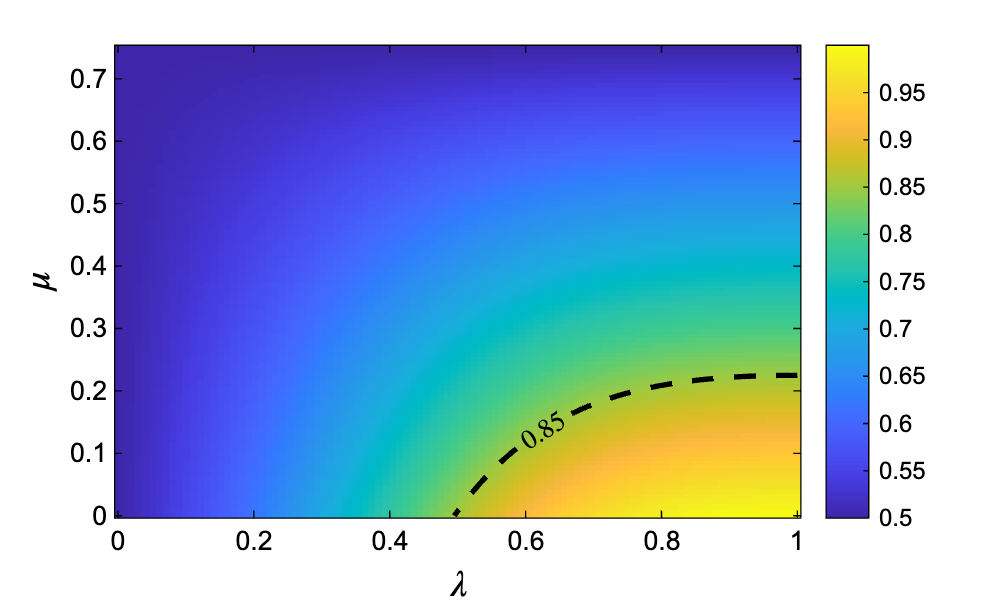

% Visualization of the fidelity as a heatmap
figure('Color', 'w');
imagesc(lambda_vec, mu_vec, Bob); % Create heatmap
set(gca, 'YDir', 'normal','FontName', 'Arial'); 

hold on; 

% Contour line and labeling
target_z = 0.85;
[C, h] = contour(lambda_vec, mu_vec, Bob, [target_z, target_z], ...
                 'LineColor', 'k', ...      
                 'LineWidth', 2, ...        
                 'LineStyle', '--');        

clabel(C, h, 'FontSize', 10, 'Color', 'k', 'Interpreter', 'latex');

hold off;

colorbar; 
colormap('parula'); 

set(gca, 'XColor', 'k', 'YColor', 'k');

xlabel('$\lambda$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);
ylabel('$\mu$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);

cb = colorbar;
cb.Color = 'k'; 

% --- EXPORT ---
exportgraphics(gcf, './figures/BB84Attack_Fidelity_4States.jpg', 'Resolution', 300);

% Visualiszation of the concurrence as a heatmap
figure('Color', 'w');
imagesc(lambda_vec, mu_vec, Entanglement); % create heatmap
set(gca, 'YDir', 'normal','FontName', 'Arial'); 

hold on; 

% Outline and labelling
target_z = 0.85;
[C, h] = contour(lambda_vec, mu_vec, Entanglement, [target_z, target_z], ...
                 'LineColor', 'w', ...      
                 'LineWidth', 2, ...        
                 'LineStyle', '--');        

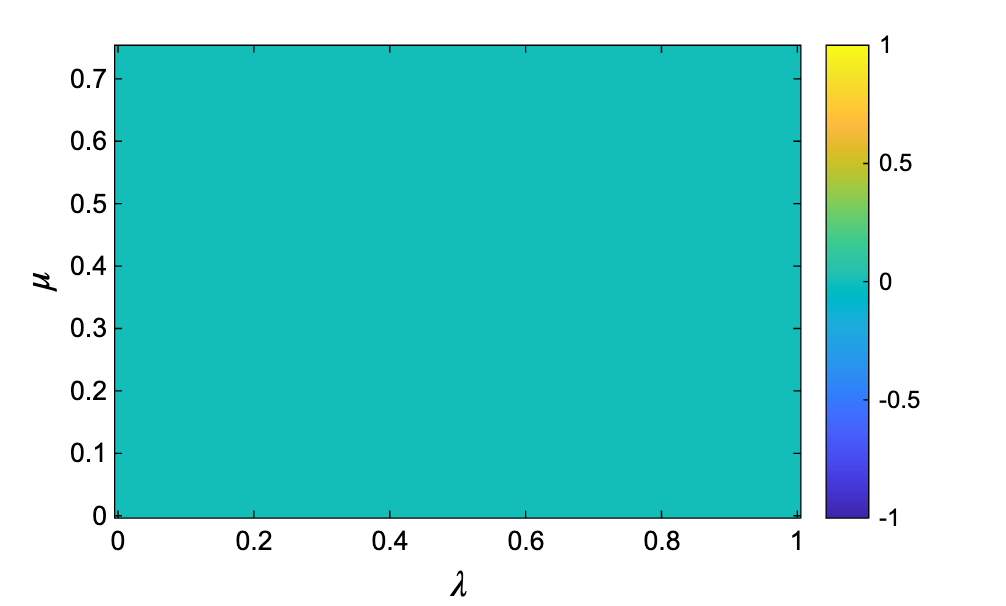



clabel(C, h, 'FontSize', 10, 'Color', 'w', 'Interpreter', 'latex');

hold off;

colorbar; 
colormap('parula'); 

set(gca, 'XColor', 'k', 'YColor', 'k');

xlabel('$\lambda$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);
ylabel('$\mu$', 'Interpreter', 'latex', 'Color', 'k', 'FontSize', 14);

cb = colorbar;
cb.Color = 'k'; 

% --- EXPORT ---
exportgraphics(gcf, './figures/BB84Attack_Concurrence_4States.jpg', 'Resolution', 300);